## Analysis of FRAP images


%   Dependencies: 
%       ReadImageJROI (Dylan Muir, MATLAB file exchange)
%       Image Processing Toolbox 
%   Fit performed as described in Xing, Rosen, Parker eLife 2020
%


## Clear figures 

% close all
% 
% if exist('PBmovie','var')
%     close(PBmovie)
% end
% clear; close all


## Input variables

%% Place 1_FRAPdata folder in the working directory, or change the path to the location of the data folder

ROInum = 2;
filename = '1_FRAPdata/1_FRAP.tif';
ROIname = ['1_FRAPdata/FRAP_RoiSet/ROI_',num2str(ROInum),'.roi'];
ROIname_unb = '1_FRAPdata/FRAP_RoiSet/ROI_unb.roi';
ROIname_bck = '1_FRAPdata/FRAP_RoiSet/ROI_bck.roi';

bleachFrame = 5; % At what frame the bleaching event occurs 

makeAllPlots = 1; % Also plot uncorrected and correction curves if = 1

thresh = 0; % if 0, equivalent to removing intra-ROI thresholding

fitEnd = 50; % what point you want the exponential fit to stop at (it will start at the bleachFrame); set=0 to fit until the last point  

unbCorr = 0; % if 0, negate correction for photobleaching (eg if unbleached ROI is sus) 

% Acquisition time characteristics: 
t1 = (1:1:5); %prebleach
t2 = (6:1:9);
t3 = (10:5:430); %postbleach
t = [t1,t2,t3];


## Import image



ts = tiffreadVolume(filename);



## Define ROIs (import from those defined in ImageJ ROI manager)

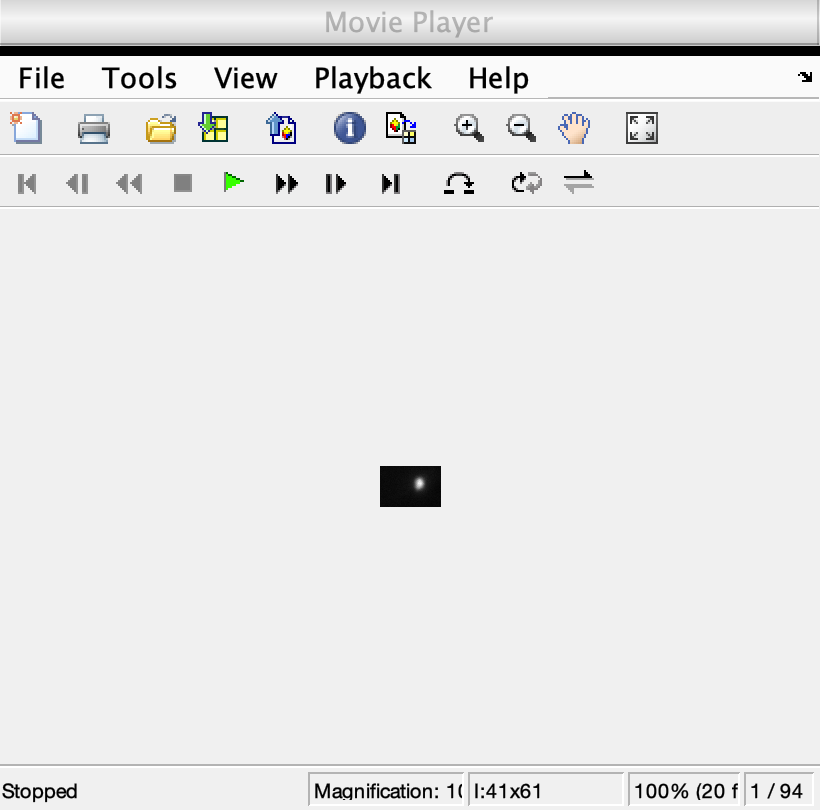

% Main PB ROI 
ROIs_PB = ReadImageJROI(ROIname);

% Isolate FRAPped particle within ROI
if strcmp(ROIs_PB.strType, 'Polygon')
    xPoly = ROIs_PB.mnCoordinates(:,1);
    yPoly = ROIs_PB.mnCoordinates(:,2);

    % Create mask same size as one frame
    ROI_PBmask = poly2mask(xPoly, yPoly, size(ts,1), size(ts,2));
    ROI_PBmask3D = repmat(ROI_PBmask, [1 1 size(ts,3)]);
    ROI_PBmask3D = uint16(ROI_PBmask3D);

    % Apply mask to all time frames
    ROI_FRAP = ts .* ROI_PBmask3D;

else % rectangular
    ROI_PB = ROIs_PB.vnRectBounds;
    yRange = ROI_PB(2) : ROI_PB(4);
    xRange = ROI_PB(1) : ROI_PB(3);
    ROI_FRAP = ts(xRange+1, yRange+1, :);
end

% Plot PB ROI 
movieData = rescale(ROI_FRAP); %auto-adjust LUT 
PBmovie = implay(movieData);



nFrames = length(ts(1,1,:));

% Define starting FRAP particle areas (auras) for bleached and unbleached particle 
%figure; imshow(ROI_FRAP(:,:,1))

FRAPp_mask_start = ROI_FRAP(:,:,1)>thresh;
FRAPp_mask_start = double(FRAPp_mask_start); % convert to numerical 1 and 0 
%figure; imshow(FRAPp_mask_start,[0 1])
[r, c] = find(FRAPp_mask_start == 1);
cm_start = round([mean(r), mean(c)]); % round to nearest integer bc image is a discrete pixel array



% Isolate other correction ROIs

ROIs_unb = ReadImageJROI(ROIname_unb);
ROIbounds_unb = ROIs_unb.vnRectBounds;
yRange = ROIbounds_unb(2) : ROIbounds_unb(4);
xRange = ROIbounds_unb(1) : ROIbounds_unb(3);
ROI_unb = ts(xRange+1, yRange+1, :);

FRAPpUnb_mask_start = ROI_unb(:,:,1)>thresh;
FRAPpUnb_mask_start = double(FRAPpUnb_mask_start); % convert to numerical 1 and 0 
%figure; imshow(FRAPpUnb_mask_start,[0 1])
[r, c] = find(FRAPpUnb_mask_start == 1);
cm_startUnb = round([mean(r), mean(c)]); % round to nearest integer bc image is a discrete pixel array


ROIs_bck = ReadImageJROI(ROIname_bck);
ROIbounds_bck = ROIs_bck.vnRectBounds;
yRange = ROIbounds_bck(2) : ROIbounds_bck(4);
xRange = ROIbounds_bck(1) : ROIbounds_bck(3);
ROI_bck = ts(xRange+1, yRange+1, :);

%figure; imshow(ROI_unb(:,:,1),[0 2000])


## Define time-invariant intensities that are used in correction of I_FRAP later

ROI_bck = double(ROI_bck);
I_bck = mean(mean(ROI_bck)); % Background intensity 
I_bck_sigma = std(std(ROI_bck));

bck_prebl = I_bck(:,:,bleachFrame-1);
bck_prebl_sigma = std(std(bck_prebl));

prebl_frame = ROI_FRAP(:,:,bleachFrame-1);
    prebl_frame = double(prebl_frame);
prebl_mask = prebl_frame>thresh;
prebl_I_fov = prebl_frame .* prebl_mask;
prebl_I = mean(mean(nonzeros(prebl_I_fov)));
N_prebl_I = numel(prebl_I_fov);
prebl_I_sigma = sqrt(prebl_I / N_prebl_I); % propogated estimate of relative error, assuming shot noise dominant

I_FRAPprebl = prebl_I - bck_prebl; % pre-bleached intensity 
I_FRAPprebl_err = propErr(prebl_I,prebl_I_sigma,bck_prebl,bck_prebl_sigma,'sub');


## Measure intensites, given the defined ROIs

for i = 1:nFrames
    bck = I_bck(:,:,i);
    bck_sigma = I_bck_sigma(:,:,i);

    pAura = FRAPp_mask_start;
    thisFrame = ROI_FRAP(:,:,i);
    thisFrame = double(thisFrame);

    pAuraUnb = FRAPpUnb_mask_start;
    thisFrameUnb = ROI_unb(:,:,i);
    thisFrameUnb = double(thisFrameUnb);



    FRAPp_mask = thisFrame>thresh;
    FRAPp_mask = double(FRAPp_mask); % convert to numerical 1 and 0

    FRAPpUnb_mask = thisFrameUnb>thresh;
    FRAPpUnb_mask = double(FRAPpUnb_mask); % convert to numerical 1 and 0


    % Get centre of mass (cm) of thresholded FRAP particle
    [r, c] = find(FRAPp_mask == 1);
    cm = round([mean(r), mean(c)]);
    cmDiff = cm-cm_start;

    [r, c] = find(FRAPpUnb_mask == 1);
    cmUnb = round([mean(r), mean(c)]);
    cmDiffUnb = cmUnb-cm_startUnb;

    % Shift aura according to shift in centre of mass relative to previous frame
    FRAPp_mask_Aura = shiftMask(pAura, cmDiff(1), cmDiff(2));
    FRAPp_fov = thisFrame .* FRAPp_mask_Aura;
    %figure; imshow(FRAPp_mask_Aura,[0 1]) % Check aura for debugging
    FRAPp_I = mean(mean(nonzeros(FRAPp_fov)));
    % Uncertainties  
    N_FRAPp = numel(FRAPp_fov);
    FRAPp_I_sigma = sqrt(FRAPp_I / N_FRAPp); % propogated estimate of relative error, assuming shot noise dominant

    FRAPpUnb_mask_Aura = shiftMask(pAuraUnb, cmDiffUnb(1), cmDiffUnb(2));
    FRAPpUnb_fov = thisFrameUnb .* FRAPpUnb_mask_Aura;
    FRAPpUnb_I = mean(mean(nonzeros(FRAPpUnb_fov)));
    N_FRAPpUnb = numel(FRAPpUnb_fov);
    FRAPpUnb_I_sigma = sqrt(FRAPpUnb_I / N_FRAPpUnb); % propogated estimate of relative error, assuming shot noise dominant

    % Define time-variant intensities (all background corrected)
    I_FRAPunc(i) = FRAPp_I - bck; % the uncorrected intensity of the bleached particle
    I_FRAPunc_err = propErr(FRAPp_I,FRAPp_I_sigma,bck,bck_sigma,'sub');
    I_FRAPunb(i) = FRAPpUnb_I - bck; % intensity of unbleached control
    I_FRAPunb_err = propErr(FRAPpUnb_I,FRAPpUnb_I_sigma,bck,bck_sigma,'sub');

    % Perform corrections and compute corrected I_FRAP (only background & PB corrections)
    if unbCorr == 0 % Negate correction 
        I_FRAPrecov(i) = (I_FRAPunc(i));
        I_FRAPrecov_err(i) = I_FRAPunc_err;
    else
        I_FRAPrecov(i) = (I_FRAPunc(i) ./ I_FRAPunb(i));
        I_FRAPrecov_err(i) = propErr(I_FRAPunc(i),I_FRAPunc_err,I_FRAPunb(i),I_FRAPunb_err,'div');

    end
    
    I_FRAP(i) = I_FRAPrecov(i) ;
    I_FRAP_err(i) = I_FRAPrecov_err(i) ;

end


## Make plot

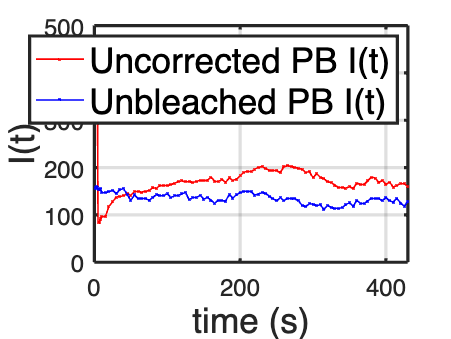

if makeAllPlots == 1 % also plot uncorrected data
    figUncorr = figure;
    hold on
    set(gcf,'color','w')
    set(gca,'LineWidth',2,'FontSize',15)
    grid on; box on
    xlabel('time (s)','FontSize',22)
    ylabel('I(t)','FontSize',22)

    plot(t, I_FRAPunc,'-x','LineWidth',1,'MarkerSize',2,'Color','r')
    plot(t, I_FRAPunb,'-x','LineWidth',1,'MarkerSize',2,'Color','b')
    legend('Uncorrected PB I(t)', 'Unbleached PB I(t)','FontSize',22)
    
end

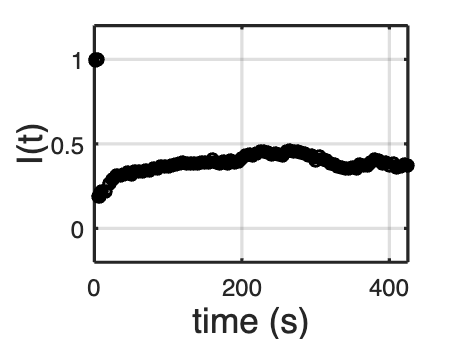


figCorr = figure;
hold on
set(gcf,'color','w')
set(gca,'LineWidth',2,'FontSize',15)
grid on; box on
xlabel('time (s)','FontSize',22)
%ylabel('Normalized, corrected I(t)','FontSize',22)
ylabel('I(t)','FontSize',22)
ylim([-0.2 1.2])

FRAPfrac = I_FRAP ./ max(I_FRAP); 
FRAPfrac_err = propErr(I_FRAP,I_FRAP_err,max(I_FRAP),0,'constDiv');
%FRAPfrac = I_FRAPunc ./ max(I_FRAPunc); % for traces with a weird unbleached PB
%FRAPfrac_err = propErr(I_FRAPunc,I_FRAPunc_err,max(I_FRAPunc),0,'constDiv');


errorbar(t, FRAPfrac,FRAPfrac_err,'o','LineWidth',2,'MarkerSize',7,'Color','k') % normalized
%plot(t, I_FRAP,'-o','LineWidth',2,'MarkerSize',5,'Color','k') % un-normalized 
xlim([0 425]); %ylim([0 1.05])

## Fit data

if fitEnd ==0 
    fitEnd = numel(I_FRAP_err);
end

t = t'; FRAPfrac = FRAPfrac';
tfit = t(bleachFrame:fitEnd); 
FRAPfracfit = FRAPfrac(bleachFrame:fitEnd);
g = fittype('Iinf + (I0 - Iinf).* exp(-k.*x)');
f0 = fit(tfit,FRAPfracfit, g,'StartPoint',[0.2 0.5 0.005])

f0 =      General model:
     f0(x) = Iinf + (I0 - Iinf).* exp(-k.*x)
     Coefficients (with 95% confidence bounds):
       I0 =      0.1707  (0.1563, 0.1851)
       Iinf =      0.4017  (0.3936, 0.4099)
       k =     0.02208  (0.01855, 0.0256)


figure(figCorr); % added to ensure the fit doesn't get plotted on previous figure    
%plot(tfit,FRAPfracfit,'or','LineWidth',3)
plot(t,f0(t),'r-','LineWidth',3);

fRec = (f0.Iinf-f0.I0)/(1-f0.I0) %fractional recovery 

fRec = 0.2786

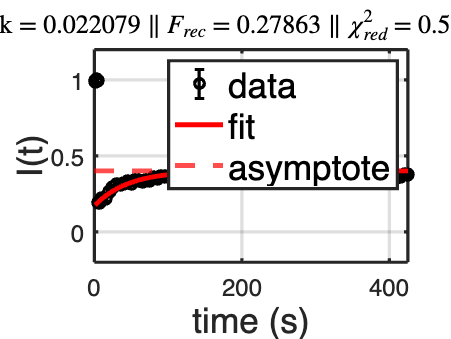

yline(f0.Iinf,'r--','LineWidth',3)

fitPoints = f0(t);
errPoints = FRAPfrac_err';
X2 = calcChiSq(FRAPfracfit, errPoints(bleachFrame:fitEnd), fitPoints(bleachFrame:fitEnd), 'classic',3); %chi sq goodness of fit (either 'classic' or 'reduced')
X2Red = calcChiSq(FRAPfracfit, errPoints(bleachFrame:fitEnd), fitPoints(bleachFrame:fitEnd), 'reduced',3); %chi sq goodness of fit (either 'classic' or 'reduced')


legend('data','fit','asymptote','FontSize',22)
title(['k = ',num2str(f0.k),' $\|$ $F_{rec}$ = ',num2str(fRec),' $\|$ $\chi^2_{red}$ = ',num2str(X2Red)],'Interpreter','latex')

## Save data

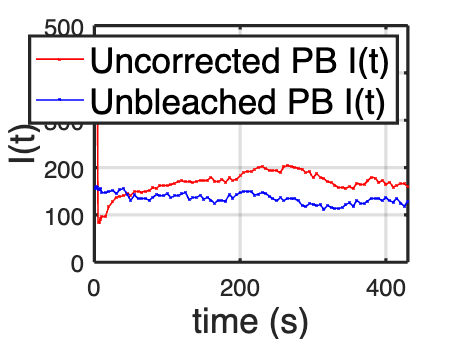

FULLdatatable = [t, I_FRAP', I_FRAPunc', I_FRAPunb', I_FRAPrecov'];
saveFoldername = 'RESULTS';

if ~exist(saveFoldername, 'dir')
    mkdir(saveFoldername);
end

filePathDat = fullfile(saveFoldername, ['FRAPvars_',num2str(ROInum),'.dat']);
save(filePathDat, 'FULLdatatable','-ascii');
filePathMat = fullfile(saveFoldername, ['FRAPvars_',num2str(ROInum),'.mat']);
save(filePathMat, 'FULLdatatable','f0','fRec');
 
% Save plots 
exportgraphics(figUncorr, [saveFoldername,'/FRAPuncorr_',num2str(ROInum),'.pdf'], 'ContentType', 'vector')

exportgraphics(figCorr, [saveFoldername,'/FRAPcorrFit_',num2str(ROInum),'.pdf'], 'ContentType', 'vector')


% Save PB movie 
% v = VideoWriter([saveFoldername,'/ROI_',num2str(ROInum),'.mp4'], 'MPEG-4');
% open(v)
% for k = 1:size(movieData, 3)
%     writeVideo(v, movieData(:,:,k));
% end
% close(v)



## Functions

% Error propagator 
function err = propErr(x,sx,y,sy,type)
    % for type 'add', 'sub', 'mult', 'div', 'constDiv'
    if strcmpi(type,'add') || strcmpi(type,'sub')
        err = sqrt(sx.^2 + sy.^2);
    elseif strcmpi(type,'mult') 
        err = (x.*y).*sqrt((sx./x).^2 + (sy./y).^2);
    elseif strcmpi(type,'div') 
        err = (x./y).*sqrt((sx./x).^2 + (sy./y).^2);
    elseif strcmpi(type,'constDiv') %y is the constant 
        err = sx./y;
    end
end


% Curvefit chi square calculator 
function chiSq = calcChiSq(y_data, err_data, f_fit, type, nParams)
    % type = 'classic' or 'reduced'; if 'classic', then value of nParams does not matter
    if strcmpi(type, 'classic') 
        chiSq = sum( (y_data - f_fit).^2 ./ err_data.^2 ) ; 
    elseif strcmpi(type, 'reduced')
        chiSq = 1./(numel(y_data) - nParams) .* sum( (y_data - f_fit).^2 ./ err_data.^2 ) ; 

    end
end

% shift the aura to new cm
function out = shiftMask(mask, dx, dy)
% shiftMask: shift an image or binary mask by dx, dy (should be integer shifts)
% uses bilinear interpolation with zero padding.

    [M, N] = size(mask);

    % Create coordinate grids for the output image
    [X, Y] = meshgrid(1:N, 1:M);

    % Compute source coordinates (where each output pixel samples from)
    Xs = X - dx;
    Ys = Y - dy;

    % Bilinear interpolation
    out = zeros(M, N);

    % Valid coordinates (inside original image)
    valid = Xs >= 1 & Xs <= N & Ys >= 1 & Ys <= M;

    % Only interpolate where valid
    Xs_valid = Xs(valid);
    Ys_valid = Ys(valid);

    % Get the four surrounding integer coordinates
    x1 = floor(Xs_valid);
    x2 = x1 + 1;
    y1 = floor(Ys_valid);
    y2 = y1 + 1;

    % Clamp to image boundaries
    x2(x2 > N) = N;
    y2(y2 > M) = M;

    % Interpolation weights
    wx = Xs_valid - x1;
    wy = Ys_valid - y1;

    % Sample the four neighbors
    f11 = mask(sub2ind([M N], y1, x1));
    f21 = mask(sub2ind([M N], y1, x2));
    f12 = mask(sub2ind([M N], y2, x1));
    f22 = mask(sub2ind([M N], y2, x2));

    % Bilinear interpolation formula
    interpValues = ...
        f11 .* (1-wx) .* (1-wy) + ...
        f21 .*    wx  .* (1-wy) + ...
        f12 .* (1-wx) .*   wy   + ...
        f22 .*    wx  .*   wy;

    % Put interpolated values back in the output
    out(valid) = interpValues;

end


